First we setup the mesh and boundary conditions using the tools in the MATLAB PDE toolbox. The geometry used is a square with the corners at (-1,-1), (-1,1), (1,1), (1,-1). A default triangular mesh is made by the toolbox.

model=createpde();
geometryFromEdges(model,@squareg);
generateMesh(model);

Second, we set the boundary conditions. The square has only one edge in the model made by MATLAB which has ID 1. The generalized Neumann conditon for a scalar PDE is $\hat{n}\cdot\left(c\vec{\nabla} u\right)+qu=g$. We set g and q equal to 0 which models an insulated sheet as no change occurs in the normal direction at the boundary. 

applyBoundaryCondition(model,"neumann","Edge",1,"g",0,"q",0);

Third, we set the coeffecients of the general second time order PDE: $m\frac{\partial^2 u}{\partial t^2}+d\frac{\partial u}{\partial t}-\vec{\nabla}\cdot \left(c\vec{\nabla}u\right)+a u=f$. 

specifyCoefficients(model,"d",1,"c",1,"a",0,"f",0,"m",0);

Fourth, we set the initial condition as $u(x,y,0)=x^2+y^2$.

setInitialConditions(model,@initfun);
Tf=1;
tN=100;
dt=Tf/tN;
results=solvepde(model,0:dt:Tf);
u=results.NodalSolution;
p=model.Mesh.Nodes; %x=p(1,:), y=p(2,:)% 

An

fsol=zeros(101,length(u));
MeanAbsoluteDiff=0;
kMax=10;
FourierandMATLABdifference=zeros(1,kMax+1);
timetaken=zeros(1,kMax+1);
for k=0:kMax
    timeStart=cputime; 
    for i=1:101
        fsol(i,:)=fourier(p(1,:),p(2,:),0.01*(i-1),2^k);
    end
    FourierandMATLABdifference(k+1)=mean(abs(u-fsol'),"all");
    timetaken(k+1)=cputime-timeStart; %CPU timer stops here%
end

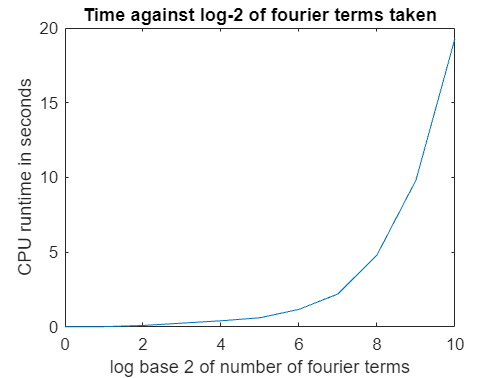

plot(0:kMax,timetaken)
title("Time against log-2 of fourier terms taken")
ylabel("CPU runtime in seconds")
xlabel("log base 2 of number of fourier terms")

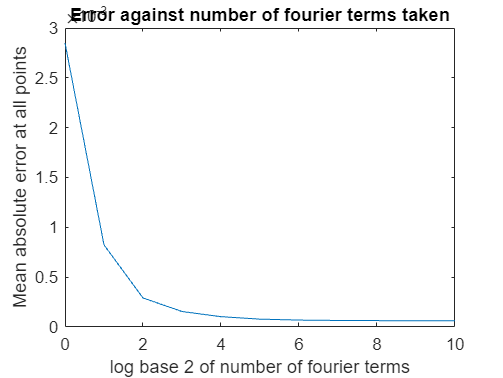

plot(0:kMax,FourierandMATLABdifference)
title("Error against number of fourier terms taken")
ylabel("Mean absolute error at all points")
xlabel("log base 2 of number of fourier terms")

Let's try the finite difference method:

We will use first the following explicit scheme for the 2D heat flow: $\frac{\partial u}{\partial t}=\beta\nabla^2u=\beta\left(\frac{\partial^2u}{\partial x^2}+\frac{\partial^2u}{\partial y^2}\right)$


$$u_{i,j,n+1}=u_{i,j,n}\left(1-2\frac{\beta \Delta t}{(\Delta x)^2}-2\frac{\beta \Delta t}{(\Delta y)^2}\right)+\frac{\beta\Delta t}{(\Delta x)^2}\left(u_{i+1,j,n}+u_{i-1,j,n}\right)+\frac{\beta\Delta t}{(\Delta y)^2}\left(u_{i,j+1,n}+u_{i,j-1,n}\right)$$


Using Von Neumann analysis and ensuring that $|p|\le1$shows that the scheme is stable when $\frac{\beta \Delta t}{(\Delta x)^2}+\frac{\beta \Delta t}{(\Delta y)^2}\le\frac12$.

We setup the number of iterations that will be done and make empty arrays to store the average absolute mean difference, CPU time taken, and $\frac{\beta \Delta t}{(\Delta x)^2}+\frac{\beta \Delta t}{(\Delta y)^2}$.

mMax=4;
L=2;
W=2;
b=1;
xN=101;
yN=101;
dx=L/(xN-1);
dy=W/(yN-1);
compindices=round(p/dx+52,0);
xspan=linspace(-L/2,L/2,xN);
yspan=linspace(-W/2,W/2,yN);
[X,Y]=meshgrid(xspan,yspan);
timetakenE=zeros(1,mMax);
StabilityIndicator=zeros(1,mMax);
FDandMATLABdifference=zeros(1,mMax);
FourierandFDdifference=zeros(1,mMax);

We start the main for loop over the different number of time steps here where it changes as a geometric sequence with ratio 2. The CPU timer is also started here.

for m=1:mMax
    timeStart=cputime; %CPU timer starts here%
    tN=4500*2^m;
    dt=Tf/tN;
    StabilityIndicator(m)=b*dt*(1/(dx)^2+1/(dy)^2); %Scheme is stable when this number is less than or equal to 0.5%

Neumann boundary conditions $\left(\frac{\partial u}{\partial x}(0,y,t)=\frac{\partial u}{\partial x}(L,y,t)=0\space\&\space \frac{\partial u}{\partial y}(x,0,t)=\frac{\partial u}{\partial y}(x,W,t)=0\right)$applied using a forward difference for the last index and a backward difference for the first index forces us to make two imaginary steps at index 1 and end at the x direction and y direction.

    temp=zeros(tN+1,xN+2,yN+2);

Initial condition is set as $u(x,y,0)=x^2+y^2$.

    for j=2:yN+1
        for i=2:xN+1
            temp(1,i,j)=((i-52)*dx)^2+((j-52)*dy)^2;
        end  
    end

The first index is always equal to the second, and the last index is always equal to the one before last in both the x and y directions.

    temp(1,1,:)=temp(1,2,:);
    temp(1,end,:)=temp(1,end-1,:);
    temp(1,:,1)=temp(1,:,2);
    temp(1,:,end)=temp(1,:,end-1);

Now we will apply the scheme over all the xs and ys at each time step.

    for j=2:tN+1
        for k=2:yN+1
            for i=2:xN+1
                temp(j,i,k)=temp(j-1,i,k)*(1-2*b*dt*(1/(dx)^2+1/(dy)^2))+(b*dt/dx^2)*(temp(j-1,i+1,k)+temp(j-1,i-1,k))+(b*dt/dy^2)*(temp(j-1,i,k+1)+temp(j-1,i,k-1));
            end
        end
        temp(j,1,:)=temp(j,2,:);
        temp(j,end,:)=temp(j,end-1,:);
        temp(j,:,1)=temp(j,:,2);
        temp(j,:,end)=temp(j,:,end-1);
    end
    timetakenE(m)=cputime-timeStart; %CPU timer stops here%

We will calculate the mean absolute difference at the points in the FEM mesh from the MATLAB toolbox. Due to the meshes being at points which aren't in the EFD matrix, we have to approximate the points.

    resiz=1:tN/100:tN+1;
    FD=zeros(101,1541);
    for i=1:1541
        FD(:,i)=temp(resiz,compindices(1,i),compindices(2,i));
    end
    FDandMATLABdifference(m)=mean(abs(u-FD'),"all");

We will calculate here the mean absolute difference between the fourier solution and the EFD scheme.

    modtemp=temp(:,2:102,2:102);
    fsol=zeros(101,101,101);
    dmodtemp=zeros(101,101,101);
    for i=1:tN/100:tN+1
        dmodtemp((i-1)/(tN/100)+1,:,:)=modtemp(i,:,:);
        fsol((i-1)/(tN/100)+1,:,:)=fourier(X,Y,dt*(i-1),1000);
    end
    FourierandFDdifference(m)=mean(abs(dmodtemp-fsol),"all");
end

A log-2 plot is done for the time taken and the absolute mean difference between the PDE matlab toolbox and each explicit finite difference scheme with different number of time steps.

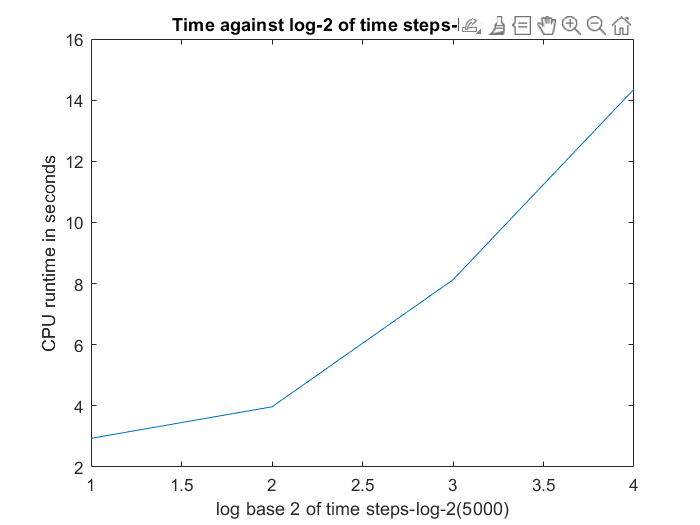

plot(timetakenE)
uicontrol("Visible","off")
title("Time against log-2 of time steps-log-2(5000)")
ylabel("CPU runtime in seconds")
xlabel("log base 2 of time steps-log-2(5000)")

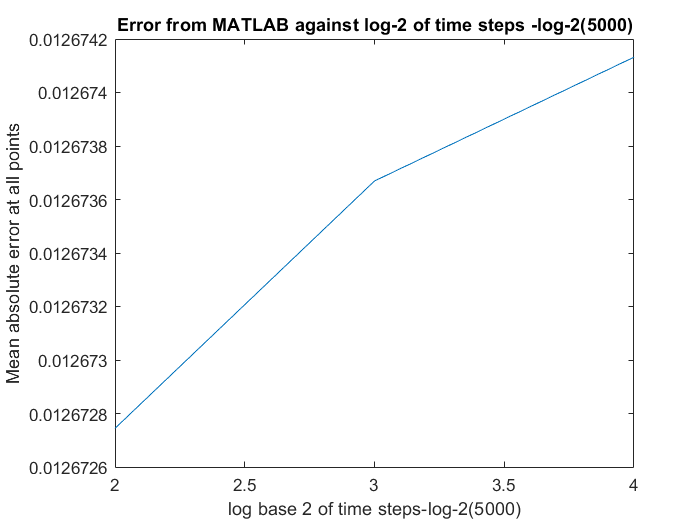

plot(FDandMATLABdifference)
title("Error from MATLAB against log-2 of time steps -log-2(5000)")
ylabel("Mean absolute error at all points")
xlabel("log base 2 of time steps-log-2(5000)")

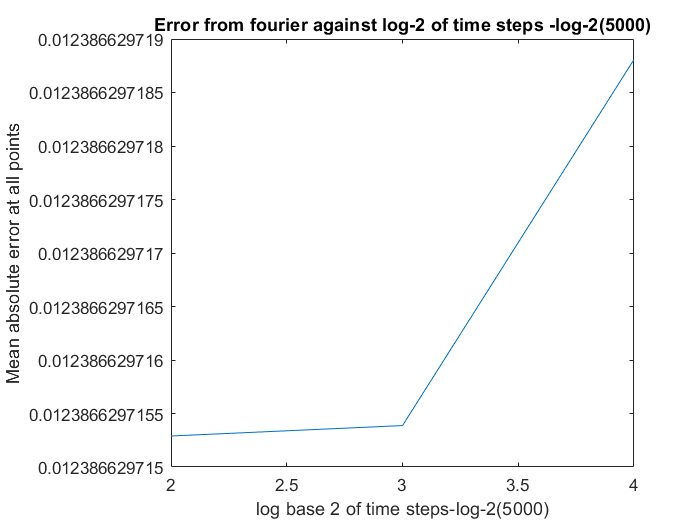

plot(FourierandFDdifference)
uicontrol("Visible","off")
title("Error from fourier against log-2 of time steps -log-2(5000)")
ylabel("Mean absolute error at all points")
xlabel("log base 2 of time steps-log-2(5000)")

StabilityIndicator

StabilityIndicator =     0.5556    0.2778    0.1389    0.0694


Changing the number of time steps barely affects the error, this is since the scheme has already achieved stability.

We will now change the number of time steps so that the scheme is unstable and observe the results.

pMax=45;
FDUnstableandMATLABdifference=zeros(1,pMax);
FourierandFDUnstabledifference=zeros(1,pMax);
timetakenEUnstable=zeros(1,pMax);
unStabilityIndicator=zeros(1,pMax);

We start the main for loop over the different number of time steps here where it changes as a arithemtic sequence starting from **** and adds 10 every iteration. The CPU timer is also started here.

for p=1:pMax
    timeStart=cputime; %CPU timer starts here%
    tN=9600+10*p;
    dt=Tf/tN;
    unStabilityIndicator(p)=b*dt*(1/(dx)^2+1/(dy)^2); %Scheme is stable when this number is less than or equal to 0.5%

Neumann boundary conditions $\left(\frac{\partial u}{\partial x}(0,y,t)=\frac{\partial u}{\partial x}(L,y,t)=0\space\&\space \frac{\partial u}{\partial y}(x,0,t)=\frac{\partial u}{\partial y}(x,W,t)=0\right)$applied using a forward difference for the last index and a backward difference for the first index forces us to make two imaginary steps at index 1 and end at the x direction and y direction.

    temp=zeros(tN+1,xN+2,yN+2);

Initial condition is set as $u(x,y,0)=x^2+y^2$.

    for j=2:yN+1
        for i=2:xN+1
            temp(1,i,j)=((i-52)*dx)^2+((j-52)*dy)^2;
        end  
    end

The first index is always equal to the second, and the last index is always equal to the one before last in both the x and y directions.

    temp(1,1,:)=temp(1,2,:);
    temp(1,end,:)=temp(1,end-1,:);
    temp(1,:,1)=temp(1,:,2);
    temp(1,:,end)=temp(1,:,end-1);

Now we will apply the scheme over all the xs and ys at each time step.

    for j=2:tN+1
        for k=2:yN+1
            for i=2:xN+1
                temp(j,i,k)=temp(j-1,i,k)*(1-2*b*dt*(1/(dx)^2+1/(dy)^2))+(b*dt/dx^2)*(temp(j-1,i+1,k)+temp(j-1,i-1,k))+(b*dt/dy^2)*(temp(j-1,i,k+1)+temp(j-1,i,k-1));
            end
        end
        temp(j,1,:)=temp(j,2,:);
        temp(j,end,:)=temp(j,end-1,:);
        temp(j,:,1)=temp(j,:,2);
        temp(j,:,end)=temp(j,:,end-1);
    end
    timetakenEUnstable(p)=cputime-timeStart; %CPU timer stops here%

We will calculate the mean absolute difference at the points in the FEM mesh from the MATLAB toolbox. Due to the meshes being at points which aren't in the EFD matrix, we have to approximate the points.

    resiz=round(linspace(1,tN,101),0);
    FD=zeros(101,1541);
    for i=1:1541
        FD(:,i)=temp(resiz,compindices(1,i),compindices(2,i));
    end
    FDUnstableandMATLABdifference(p)=mean(abs(u-FD'),"all");

We will calculate here the mean absolute difference between the fourier solution and the EFD scheme.

    modtemp=temp(:,2:102,2:102);
    fsol=zeros(101,101,101);
    dmodtemp=zeros(101,101,101);
    for i=1:101
        tspan=round(linspace(1,tN,101),0);
        dmodtemp(i,:,:)=modtemp(tspan(i),:,:);
        fsol(i,:,:)=fourier(X,Y,dt*tspan(i),1000);
    end
    FourierandFDUnstabledifference(m)=mean(abs(dmodtemp-fsol),"all");
end

A log-2 plot is done for the time taken and the absolute mean difference between the PDE matlab toolbox and each explicit finite difference scheme with different number of time steps.

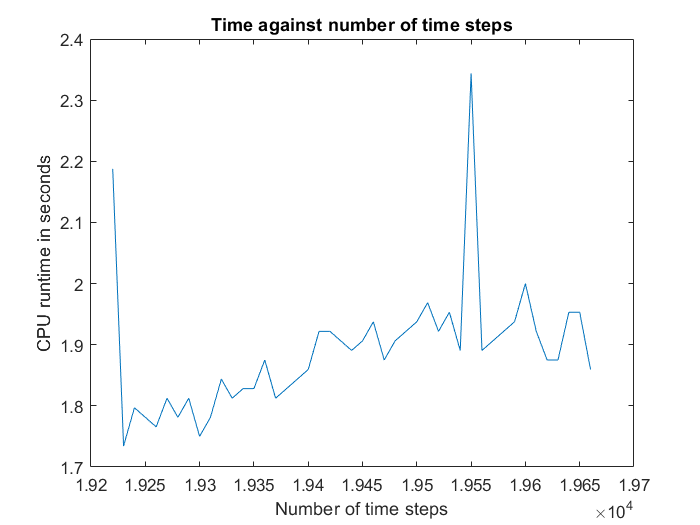

plot(19220:10:19660,timetakenEUnstable)
uicontrol("Visible","off")
title("Time against number of time steps")
ylabel("CPU runtime in seconds")
xlabel("Number of time steps")

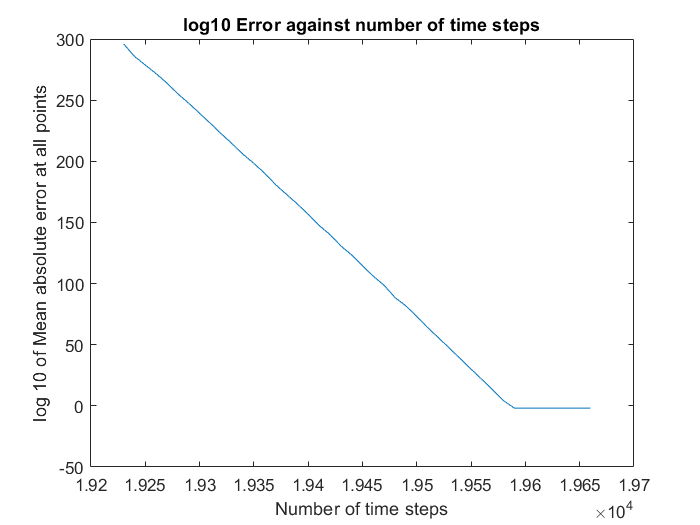

log10EUMd=log10(FDUnstableandMATLABdifference);
plot(19220:10:19660,log10EUMd)
title("log10 Error against number of time steps")
ylabel("log 10 of Mean absolute error at all points")
xlabel("Number of time steps")

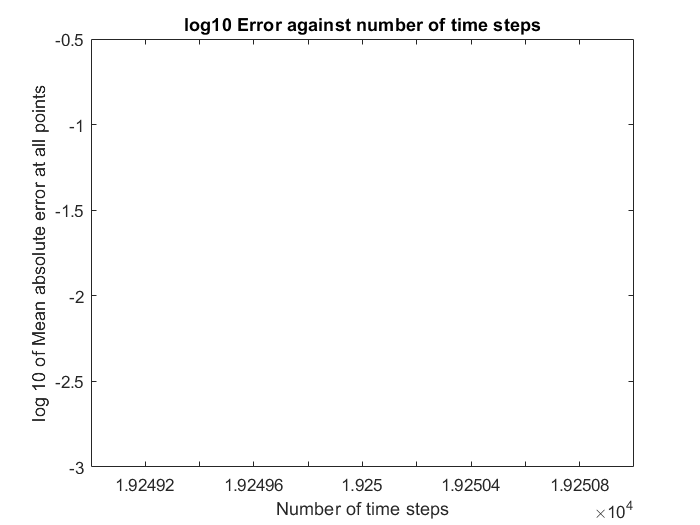

log10EUMd=log10(FourierandFDUnstabledifference);
plot(19220:10:19660,log10EUMd)
title("log10 Error against number of time steps")
ylabel("log 10 of Mean absolute error at all points")
xlabel("Number of time steps")

unStabilityIndicator

unStabilityIndicator =     0.5203    0.5198    0.5192    0.5187    0.5181    0.5176    0.5171    0.5165    0.5160    0.5155    0.5149    0.5144    0.5139    0.5133    0.5128    0.5123    0.5118    0.5112    0.5107    0.5102    0.5097    0.5092    0.5086    0.5081    0.5076    0.5071    0.5066    0.5061    0.5056    0.5051    0.5045    0.5040    0.5035    0.5030    0.5025    0.5020    0.5015    0.5010    0.5005    0.5000    0.4995    0.4990    0.4985    0.4980    0.4975


initfun is used as the initial condition which is $u(x,y,0)=x^2+y^2$.

function u0=initfun(location)
     u0=location.x.^2+location.y.^2;
end

The fourier expansion of the solution:


$$u(x,y,t)=\frac23 +\frac{4}{\pi^2}\sum_{n=1}^{\infty}\frac{(-1)^n}{n^2}\cos(n\pi x)+\frac{4}{\pi^2}\sum_{n=1}^{\infty}\frac{(-1)^n}{n^2}\cos(n\pi y)$$


is made as a function called "fourier" with inputs x, y, t, and n.

function f=fourier(x,y,t,n)
     xsum=0;
     ysum=0;
     for i=1:n
         xsum=xsum+(((-1)^i)/i^2)*cos(pi*i*x)*exp(-pi^2*i^2*t);
     end
     for i=1:n
         ysum=ysum+(((-1)^i)/i^2)*cos(pi*i*y)*exp(-pi^2*i^2*t);
     end
     f=2/3+(4/pi^2)*xsum+(4/pi^2)*ysum;
end